# Compute Sample ACF and PACF

Visually and qualitatively assess autocorrelation in a time series is 57 consecutive days of overshorts from a gasoline tank in Colorado by computing and plotting the sample ACF and PACF. 

## Load Data

Load the time series of overshorts.

load Data_Overshort

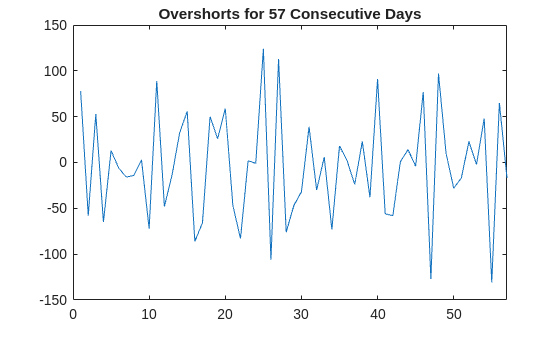


y = Data;
n = length(y);

figure
plot(y)
xlim([0 n])
title("Overshorts for 57 Consecutive Days")

The series appears to be stationary. 

## Plot Sample ACF and PACF

Plot the sample ACF and PACF. 

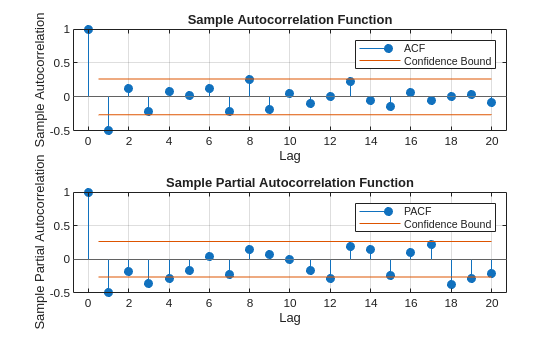

figure
tiledlayout(2,1)
nexttile
autocorr(y)
nexttile
parcorr(y)

The sample ACF and PACF exhibit significant autocorrelation. The sample ACF has significant autocorrelation at lag 1. The sample PACF has significant autocorrelation at lags 1, 3, and 4. 

The distinct cutoff of the ACF combined with the more gradual decay of the PACF suggests an MA(1) model might be appropriate for this data. 

## Store Sample ACF and PACF Values

Set variables to the sample ACF and PACF values up to lag 15. 

acf = autocorr(y,NumLags=15);
pacf = parcorr(y,NumLags=15);
[length(acf) length(pacf)]

ans =     16    16


The outputs `acf` and `pacf` are vectors storing the sample autocorrelation and partial autocorrelation at lags 0, 1,...,15 (a total of 16 lags). 

*Copyright 20 The MathWorks, Inc.*